# Решение прямой задачи нестационарной нелинечной теплопроводности методом конечных разностей

## Уравнение теплопроводности

изменение запасенной в объеме энергии = поток энергии, выходящий из объема вовне + произведенная внутренними источниками энергия


$$\frac{d}{dt} \int\int\int_V \rho c (T) \, dV = - \int\int_S \vec{q} \cdot \vec{n}  dS +\int\int\int_V  Q \, dV$$


Теорема Гаусса (теорема о дивергеции) связывает суммарный поток вектора перпендикулярной повехности с суммарной дивергенцией вектора в объеме


$$\int\int_S \vec{q} \cdot \vec{n}  dS =  \int\int\int_V \nabla\cdot\vec{q}dV$$


Уравнение теплопроводности:


$$ C(T) \frac{\partial T}{\partial t}  = -\nabla \cdot\vec{q}(\vec{r}, T) + Q(T,\vec{r})  $$


 $C(T)$- теплоемкость

$\vec{q}(\vec{r},T)$ - вектор плотности теплового потока


$$\vec{q}(\vec{r},T)=- \lambda(T,\vec{r}) \nabla T(\vec{r})$$


$\lambda(T,\vec{r})$ - температуропроводность (может зависеть как от температуры, так и от координаты), зависимость от температуры автоматически делает теплопровность, зависящей от координаты (по крайней мере для неравномерного распределения темпеатуры).

$Q(T,\vec{r})$ - плотность внутренних источников


$$ C(T) \frac{\partial T}{\partial t}  = \nabla \cdot (\lambda(T,\vec{r})\nabla T(\vec{r}))+ Q(T,\vec{r})  $$


$\nabla = \sum_i \hat{x}_i \frac{\partial}{\partial x_i}$ - градиент в ортогональной декартовой системе координат

$\nabla\cdot = \sum_i \hat{x}_i \cdot \frac{\partial}{\partial x_i}$ - дивергенция

### Одномерная задача

Для одномерной задачи (слой, бесконечный в латеральном направлении) с изотропной теплопроводностью, зависящей только от температуры при остуствии внутренних источников тепла, получаем нелинейное нестационарное дифференциальное уравнение в частных производных параболического типа (слева первая производная, справа - вторая):


$$ C(T) \frac{\partial T}{\partial t}  = \frac{\partial}{\partial x} (\lambda(T) \frac{\partial T}{\partial x} )$$


Для программирования и решения обратных задач, удобно переписать это выражение в виде: 

$\frac {1}{a(T)} \frac{\partial T}{\partial t}  =\frac{\partial^2 T}{\partial x^2} +   \frac{\lambda'(T)}{\lambda(T)}(\frac{\partial T}{\partial x})^2$                                                                    (1)

Здесь $a(T) =\frac {\lambda(T)}{c_p(T)\rho}$  - коэффициент температуропроводности, а $\lambda'(T)=\frac {d\lambda}{dT}$. Правая часть данного уравнения содержит линейный дифференциальный оператор и  нелинейную часть. 

Чтобы решить ДУЧП, необходимо задать начальные условия - распределение температуры в слое:


$$T(x,0) = \phi(x),x   \in [0,b]$$
  

И граничные условия, граничные условия могут быть различными:

Дирихле (1 -го рода):

$T(x,t)|_{x=0,x=b} = f(t), t \in [0,t_m]$ - температура на границе

Неймана (2 - го рода):

$\lambda\frac{\partial T}{\partial x}(x,t)|_{x=0,x=b} = q(t), t \in [0,t_m]$ - тепловой поток на границе

Третьего рода:


$$\lambda\frac{\partial T}{\partial x}(x,t)|_{x=0,x=b} = R(T(x,t)|_{x=0,x=b}), t \in [0,t_m]$$


$R(T(x,t)) = h(T(x,t))(T(x,t) - T_{\inf})$ - конвекция

$R(T(x,t)) = \sigma\epsilon(T(x,t))(T^4(x,t) - T^4_{ref})$ - излучение

Уравнение (1) - нелинейное, поэтому в общем случае, если теплопроводность зависит от температуры, оно может быть решено только численно.

Полная постановка прямой задачи для слоя заданной толщины будет иметь, например, для ГУ 1 - го рода сверху и 2 - го рода снизу следующий вид: 


$$\begin{cases} \matrix{
\frac {1}{a(T)} \frac{\partial T}{\partial t}  =\frac{\partial^2 T}{\partial x^2} +   \frac{\lambda'(T)}{\lambda(T)} (\frac{\partial T}{\partial x})^2 \cr 
T(x,0) = \phi(x),x   \in [0,b] \cr
T(b,t) = f(t), t \in [0,t_m] \cr
-\lambda(T(b,t))\frac{\partial T}{\partial x} (b,t) = \tilde {q}(t)
} \end{cases}$$
                                                                                    

## Решение прямой задачи методом конечных разностей

### Аппроксимация производных конечными разностями

Для решения уравнения надо вначале дискретизовать сам дифур:

$\frac {1}{a(T)} \frac{\partial T}{\partial t}  =\frac{\partial^2 T}{\partial x^2} +   \frac{\lambda'(T)}{\lambda(T)} (\frac{\partial T}{\partial x})^2$                                                                                    **(2)**

Данное уравнение имеет первую производную по времени и вторую и первую призводную по координате. Кроме того, в нем есть нелинейная часть (самое правое слагаемое). Обратим внимание, что когда теплопроводность не зависит от температуры, этот слен становится равным нулю и телпоперенос определяется только температуропроводностью.

Будем дискретизовать его на равномерной сетке. 

$x_n=\Delta x(n-1), n = 1...N$ - равномерная сетка по координате

$t_m=\Delta t(m-1), m = 1...M$ - равномерная сетка по времени

Пока не будем задумываться как учитывать границы, наша задача просто заменить дифференциальный операторы в  уравнении (1) дискретными сеточными операторами.

Можно разными способами выразить приближенную производную через значение в узлах сетки.

#### Производная по времени (обратное дифференцирование)

Формула Тейлора:


$$T(t+a)=T(t) + a\frac{dT}{dt}(t) + + a^2\frac{1}{2}\frac {d^2 T} {dt^2}(t) + ... + a^q\frac{1}{q!}\frac {d^q T} {dt^q}(t) + o(a^q)$$


Отсюда можно получить выражение для температуры в предыдущие моменты времени, так, например, температура 

$T^{m-k}$ в момент времени, отстоящий назад во времени от момента времени $t_m$  на $k\Delta t$, может  быть выражена через $T^{m}$:


$$T^{m-k}=T^m - k\Delta t\frac{dT}{dt}_m +  (k\Delta t)^2\frac{1}{2}\frac {d^2 T} {dt^2}_m + ... + (k\Delta t)^q\frac{1}{q!}\frac {d^q T} {dt^q}_m + o((k\Delta t)^q)$$
 

Мы должны рассчитывать производную в $m+1$- й момент времени, соотвественно, мы будем выражать предыдущие моменты времени через $m+1$- й.  

Воспользуемся формулой первого порядка :


$$ T^{m} = T^{m+1} - \Delta t \frac{dT}{dt}^{m+1} + o(\Delta t)$$
  


$$\[
\frac{\partial T}{\partial t}_{m+1,n} \approx \frac{T^{m+1}_n - T^{m}_n}{\Delta t}
\]$$


То есть, берутся температуры n - го элемента сетки в m и m+1 - й моменты времени. 

Это, так называемая **BFD1** - **B**ackward **F**inite **D**ifference первого рода.

Аналогично можно вывести формулы более высокого порядка для производной в точке $m+1$ из точек в предыдущие моменты времени, для примера посмотрим на второй порядок **BFD2**: 

Мы должны выразить $T^{m}$ и $T^{m-1}$ через производную и значение функции в $m+1$- й момент времени 


$$a = -\Delta t: T^{m} = T^{m+1} - \Delta t \frac{dT}{dt}^{m+1} +\frac{1}{2} \Delta t^2\frac {d^2 T} {dt^2}^{m+1} + o(\Delta t^2)$$
  


$$a = -2\Delta t: T^{m-1} = T^{m+1} - 2\Delta t \frac{dT}{dt}^{m+1} + 2\Delta t^2\frac {d^2 T} {dt^2}^{m+1}+ o(\Delta t^2)$$
  

Если  предположить, что $\partial T / \partial t ^{m+1} = w_1T^{m+1} + w_0T^m + w_{-1}T^{m-1}$, то есть наша задача - найти неизвестные коэффициенты, выражающие производную температуры в $m+1$-й момент времени через предыдущие.

Подставив выражения  для разложений Тейлора в эту формулу, получим:


$$\frac { dT}{dt} ^{m+1}= (w_1 + w_0 + w_{-1})T^{m+1} - (w_0 \Delta t + 2w_{-1} \Delta t)\frac {dT}{dt}^{m+1} +  (\frac{1}{2} w_0 \Delta t ^2 + 2w_{-1} \Delta t^2)\frac {d^2T}{dt^2}^{m+1} + o(\Delta t^2)$$
 

Так как это равенство должно выполняться для любого момента времени, то :


$$[\matrix {
1 & 1 &1 \cr 
0 & -\Delta t & -2 \Delta t \cr 
0& \frac{1}{2} \Delta t^2 & 2w_{-1}\Delta t^2 }] 
[\matrix{
w_1 \cr
w_0 \cr
w_{-1} 
}] = [\matrix {0 \cr 1 \cr 0}]$$


Из последнего: $ w_0  = - 4w_{-1}$ , из второго $w_0=-\frac{1}{\Delta t} - 2w_1$ : $w_{-1} = \frac{1}{2\Delta t}$, $w_0 = -\frac{4}{2\Delta t}$, $w_1 = \frac{3}{2\Delta t}$


$$\[
\frac{\partial T}{\partial t}_n^{m+1} \approx  
w_1T^{m+1} + w_0T^m + w_{-1}T^{m-1} = \frac{3T^{m+1}_n - 4T^{m}_n + T^{m-1}_n }{2\Delta t}
\]$$


#### Производная по координате

Для расчета первой производной по координате  можно воспользоваться  выражением для центральной производной, которая дает ($O(\Delta x ^2)$):


$$\[
\frac{\partial T}{\partial x} _n^m \approx \frac{T^{m}_{n-1} - T^{m}_{n+1}}{2\Delta x}
\]$$



$$\[
D_{xsym} = \frac{1}{2\Delta x}[
\matrix{
0 & 1 & 0 & \cdots & 0 \cr
1 & 0 & -1 & \cdots & 0 \cr
\vdots & & \ddots & \ddots & \vdots \cr
0 & \cdots & 1 & 0 & -1 \cr
0 & \cdots & \cdots & 0 & -1
}
]$$


N = 3;
M = 40;
a = zeros(M,N)

a =      0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0


D = Dt(M)

D =     -1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0    -1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0    -1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0    -1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0    -1  

Dsym = Dtsym(M)

Dsym =          0    0.5000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.5000         0    0.5000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0   -0.5000         0    0.5000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0 

D*rand(M,N)

ans =     0.0911   -0.0572    0.4792
   -0.7788    0.3840   -0.2456
    0.7864    0.0297   -0.0355
   -0.2810   -0.6083    0.3675
   -0.5348    0.3029   -0.6314
    0.1810   -0.0442    0.4714
    0.2684    0.2007   -0.0035
    0.4106    0.0631   -0.3733
    0.0074    0.0453    0.1874
   -0.8073   -0.4787   -0.4920


ppp = [2,0.4,4,1,2];
x = linspace(0,1,M)';
y = polyval(ppp,x);
h = x(end) - x(end-1)

h = 0.0256

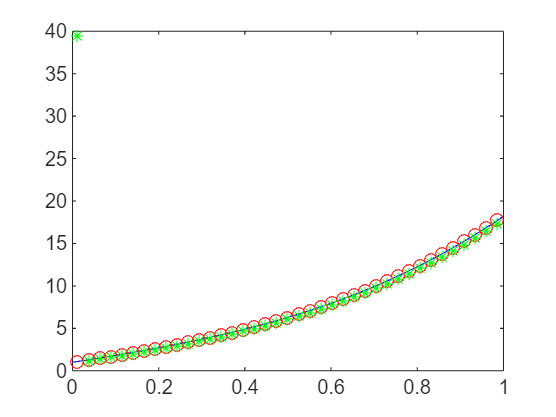

y_der = polyval(polyder(ppp),x);
xmean = (x(1:end-1) + x(2:end))/2;
plot(x,y_der,"b",xmean,D*y/h,"or",xmean,Dsym*y/h,"*g")

#### Почему для расчета производной по времени не годится центральная производная?

Центральная производная дает нам производную в $m$- й веремени, а обратная производная - производную в m+1, таким образом:

$\frac{3T^{m+1}_n - 4T^{m}_n + T^{m-1}_n }{2\Delta t}  \approx \frac {\partial T}{\partial t}_n^{m+1}$  - производная в $m+1$ - й  момент времени

$\frac{T^{m+1}_n -  T^{m-1}_n }{2\Delta t}  \approx \frac {\partial T}{\partial t}_n^{m}$ - производная в $m$ - й момент времени

Теперь посмотрим на оператор второй производной:

$\[
\frac{\partial^2 T}{\partial x^2}_{m+1,n} \approx \frac{T^{m+1}_{n+1}  - 2T^{m+1}_{n} +T^{m+1}_{n-1}}{\Delta x^2}
\]$ - 


$$\[
D^2 = \frac{1}{\Delta x^2}
[\matrix{
-2 & 1 & 0 & \cdots & 0 \cr
1 & -2 & 1 & \cdots & 0 \cr
0 & 1 & -2 & \cdots & 0 \cr
\vdots & \vdots & \vdots & \ddots & 1 \cr
0 & 0 & 0 & 1 & -2
}
]$$


## Конечно-разностные операторы в уравнении теплопроводности

### Явные и неявные схемы

Тут можно обратить внимание, что так как у нас есть два индекса - один соотвествует координате, а другой  - времени, то возможны явная и неявная схемы. 

В явной схеме температуры на следующем шаге по времени выражаются через температуры на текущем шаге по времени (m+1 стоит  слева, а m - справа в рекурентном соотношении для дифференциального оператора), в неявных схемах m+1 стоит  и слева, и справа .

Построим сетку для координаты и времени:


$$x_n = (n-1)\Delta x, n\in 1...N$$
 


$$t_m = (m-1)\Delta t, m\in 1...M$$
 

Задача состоит в том, чтобы после замены дифференциальных операторов конечно-разностными, распределение температуры по толщине образца в $m+1$-й момент времени, можно было выразить через распределение температуры в $m$ - й момент времени. 


$$
\frac {1}{a(T)} \frac{\partial T}{\partial t}  =\frac{\partial^2 T}{\partial x^2} +   \frac{\lambda'(T)}{\lambda(T)} (\frac{\partial T}{\partial x})^2$$
         

В данном уравнении справа у нас есть два члена:

первый - линейный дифференциальный оператор второго порядка  - вторая производная по координате 

второй - квадратичный, для дискретизации можно, вообще говоря использовать разные варианты. 

Вначале рассмтрим первый член правой части (линейный), для дискретизации можно использовать **явную** схему, **неявную** схему и схему **Кранка-Николсона** (комбинацию двух вариантов)

**Явная** схема дискретизации:

$\[
\frac{\partial^2 T}{\partial x^2}_{mn} \approx \frac{T^{m}_{n+1}  - 2T^{m}_{n} +T^{m}_{n-1}}{\Delta x^2}
\]$ - явная (explicit) схема дискретизации, производная считается для m-го момента времени.

**Неявная** схема дискретизации:

$\[
\frac{\partial^2 T}{\partial x^2}_{mn} \approx \frac{T^{m+1}_{n+1}  - 2T^{m+1}_{n} +T^{m+1}_{n-1}}{\Delta x^2}
\]$ - неявная (implicit) схема дискретизации, так как для расчета производной координате используется (m+1)-й момент времени


$$\[
\frac{\partial^2 T}{\partial x^2}_{mn} \approx\frac{1}{\Delta x^2} [ \theta (T^{m+1}_{n+1}  - 2T^{m+1}_{n} +T^{m+1}_{n-1})+ (1 - \theta)(T^{m}_{n+1}  - 2T^{m}_{n} +T^{m}_{n-1})]
\]$$


**Кранк-Николсон:**


$$\theta=1/2$$


Для производной по времени, стоящей слева может быть использовано выражение как второго, так и первого порядка точности.

## Большая таблица различных схем

Вначале будем рассматрицать чисто конечно-разностные схемы без привязки к граничным условиям, следовательно во всех рассуждениях данного раздела первые и последние строки матриц, а также правой части выражений будут "не верными", их нужно будет потом модифицировать под конкретные граничные условия.


$$
\frac {1}{a(T)} \frac{\partial T}{\partial t}  =\frac{\partial^2 T}{\partial x^2} +   \frac{\lambda'(T)}{\lambda(T)} (\frac{\partial T}{\partial x})^2$$
         

$F_{n}^m = \frac{a_{n}^m\Delta t}{\Delta x^2$ - число Фурье

 $\phi_{n}^m  = \frac{{\lambda '}_n^m}{4\lambda_n^m}$ - коэффициент нелинейной части ($\phi = \frac{1}{4} \frac {d}{dT} (ln(\lambda(T) |_{T=T_{mn}}$)

Какие есть основные моменты относительно уравнения:

- Производная по времени (левая часть уравнения) различные формы обратной производной (BDF1, BDF2, BDF3...)

- Момент времени аппроксимации второй производной (явная m,неявная m+1, Кранк-Николсон)

- Момент времени для нелинейной части (m или m+1)

- Момент времени расчета теплофизических свойств (m или m+1)

1 - Самая простая явная схема, обладает условной сходимостью

2 - Неявная схема обладает, обладает безусловной сходимостью

3 - Схема Кранка-Никлсона (сердняя между явной и неявной) дает относительно "дешево" аппроксимацию второго порядка по времени

4 - Схема второго порядка сходимости по времени и координате, второй порядок по времени достигается использованием обратного дифференцирования BDF2.

5 - Схема второго порядка, исопльзующая как схему Кранка-Николсона, так и BDF2 для аппроксимации производной по времени

6 - Сочетает в себе обратное дифференцирования, Кранка-Николсона и неявную схему для нелинейного члена, в этом случае для вычисления распределения температуры в $m+1$-й момент времени, из-за того, что неизвестная $T^{m+1}$сходит под квадратом, теперь нужно пользоваться численным методом решения системы нелинейных уравнений (например, методом Ньютона-Рафсона)

7 - Тоже самое, что и пункт 5, но теперь все свойства также рассчитываются для m+1 - го шага

Далее получим матричные выражения для приведенных в таблице разностных схем.

Заголовки схем будут даваться по принципу: 

**тип производной по времени = тип второй производной + тип нелинейной части**

## Схема 1. BFD1 = explicit + explicit

Это самая простая схема, слева стоит аппроксимация производной первого порядка, производная второго порядка аппроксимируется явной схемой и нелинейный член выражается через цетральную явную производную. Температура в $m+1$- й момент времени входит столько в обратную производную, то распределение температуры на следующем шаге можно получить в одно матричное умножение

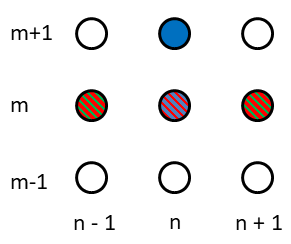                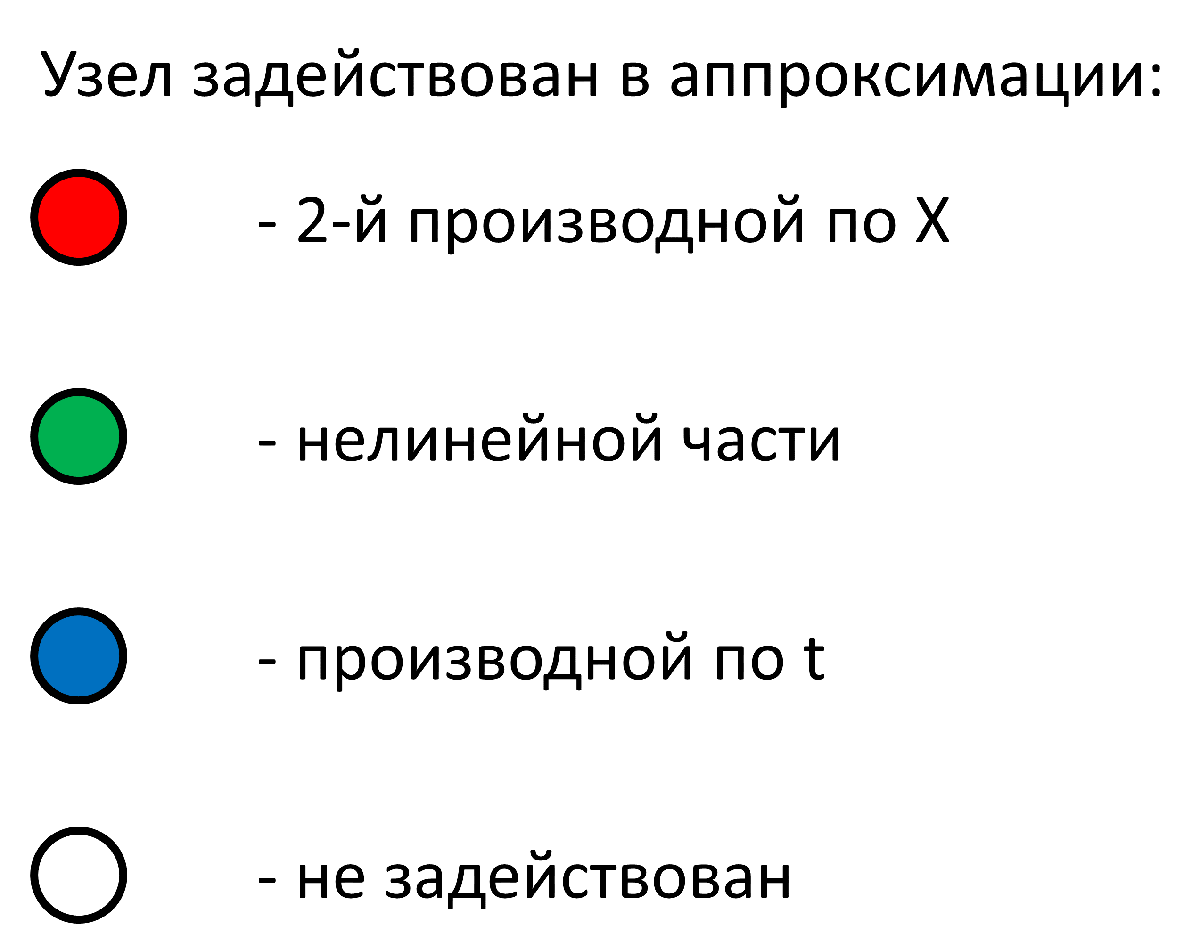


$$(T^{m+1}_n - T^{m}_n) = F_n^m[T^{m}_{n+1}  - 2T^{m}_{n} +T^{m}_{n-1}] +F_{n}^m \phi_{n}^m (T^{m}_{n-1} - T^{m}_{n+1})^2$$



$$T^{m+1}_n =F_n^mT^{m}_{n+1} +(1-2F_n^m) T^{m}_n + F_n^mT^{m}_{n-1} + F_{n}^m \phi_{n}^m (T^{m}_{n-1} - T^{m}_{n+1})^2$$


Это выражение можно записать в матричной форме.

Пусть у нас есть вектор- столбец распределения температуры по толщине в текущий момент времени $\vec{T}^m$, тогда распределение температур в следующий момент времени, выражается через сумму линейной и нелинейной компонент:

$\vec{T}^{m+1} = A^m\vec{T}^m + \vec{b}^m$                                                                                    (2)

где


$$
{A}^m = [
\matrix{
1 - 2F_1^m & F_1^m & 0 & \cdots & 0 \cr
F_{2}^m & 1 - 2F_{2}^m & F_{2}^m & \cdots & 0 \cr
0 & F_{3}^m & 1 - 2F_{3}^m & \cdots & 0 \cr
\vdots & \vdots & \vdots & 1 - 2F_{N-1}^m & F_{N-1}^m \cr
0 & 0 & 0 & F_{N}^m & 1 - 2F_{N}^m
}
]$$


$A^m$ - трехдиагональная матрица


$$[\vec{b}^m(\vec{T}^m)]_n= F_{n}^m \phi_{n}^m (T^{m}_{n-1} - T^{m}_{n+1})^2$$


Индекс  $n$ у нас меняется от 1 до N поэтому не понятно пока, как правильно получить выражения для первой и последней строки матрицы $A^m$ и для первого и последнего элемента вектора $\vec{b}^m$.

Данная схема наызвается явной, так как выражение (2) не требует инвертирования матрицы, выражение получается просто умножением матрицы на вектор распределения температур в предыдущий момент времени.

Формулу для вектора $\vec{b}^m$ можно переписать в матричном виде через матрицу центральной производной:


$$\[
D =[
\matrix{
0 & -1 & 0 & \cdots & 0 \cr
1 & 0 & -1 & \cdots & 0 \cr
\vdots & & \ddots & \ddots & \vdots \cr
0 & \cdots & 1 & 0 & -1 \cr
0 & \cdots & \cdots & 1 & 0
}
]$$


Тогда вектор $\vec{b}^m$ :


$$\vec{b}^m(\vec{T}^m)= \mathrm{diag}(\vec{F}^{m}\circ\vec{\phi}^{m})(D\vec{T}^m\circ D\vec{T}^m)$$
  

где $\vec{F}^m = \matrix{ F_1^m \cr \vdots \cr F_N^m}$ , $\vec{\phi}^m = \matrix{ \phi_1^m \cr \vdots \cr \phi_N^m}$ - вектора коэффициентов 

 $\circ$ - поэлементное умножение (произведение Адамара) $\vec{c}(\vec{x}) = \vec{a} \circ \vec{b}$ : $[\vec{c}]_i = [\vec{a}]_i[\vec{b}]_i$ : $\vec{c} =[ \matrix{a_1b_1 \cr \vdots \cr a_n b_n}]$

$\mathrm{diag}(\vec{a})$ - операция диагонализации вектора, $\mathrm{diag}(\vec{a}) = [ \matrix{a_1 & \dots &0\cr 0&\ddots & 0\cr 0 & \dots & a_N  }]$

Операция  $\mathrm{diag}(\vec{a})A$ умножает каждую строку матрицы на соответствующую координату вектора $\vec{a}$, если умножать матрицу справа $A\cdot \mathrm{diag}(\vec{a})$ на диагонализованный вектор, то каждый столбец матрицы умножается на соотвествующую координату

clearvars
a = sym('a',[3,1]);
b = sym('b',[2,1]);
C = sym('c',[3,2]);
diag(a)*C

$$ans = \left(\begin{array}{cc} a_{1}\,c_{1,1} & a_{1}\,c_{1,2}\\ a_{2}\,c_{2,1} & a_{2}\,c_{2,2}\\ a_{3}\,c_{3,1} & a_{3}\,c_{3,2} \end{array}\right)$$

C*diag(b)

$$ans = \left(\begin{array}{cc} b_{1}\,c_{1,1} & b_{2}\,c_{1,2}\\ b_{1}\,c_{2,1} & b_{2}\,c_{2,2}\\ b_{1}\,c_{3,1} & b_{2}\,c_{3,2} \end{array}\right)$$

% в матлаб произведение адамара работает добавлением точки 
a.*C

$$ans = \left(\begin{array}{cc} a_{1}\,c_{1,1} & a_{1}\,c_{1,2}\\ a_{2}\,c_{2,1} & a_{2}\,c_{2,2}\\ a_{3}\,c_{3,1} & a_{3}\,c_{3,2} \end{array}\right)$$

C.*transpose(b)

$$ans = \left(\begin{array}{cc} b_{1}\,c_{1,1} & b_{2}\,c_{1,2}\\ b_{1}\,c_{2,1} & b_{2}\,c_{2,2}\\ b_{1}\,c_{3,1} & b_{2}\,c_{3,2} \end{array}\right)$$

Матричное выражение дает неправильное значение для первого и последнего элемента так как для вычисления, например, первого элемента   $[\vec{b}^m(\vec{T}^m)]_1= F_{1}^m \phi_{1}^m (T^{m}_{0} - T^{m}_{2})^2$ нам требуется знать $T^{m}_{0}$ - а координаты с нулевым индексом у нас нет. Аналогично и для последнего элемента - требуется $N+1$- й индекс. Но это не страшно, так как значения первого и последнего элементов вектора $\vec{b}^m$ будут

получаться из граничных условий.

#### Устойчивость  явной схемы

    Немного про устойчивость разностных схем, в общем случае, в особенности для достаточно сложных уравнений это целая наука, но общую идею можно проиллюстрировать для простого случая решения линейного уравнения (если теплопроводность от температуры не зависит, то вектор $\vec{b}^m$ будет равен нулю, а матрица $A^m =A$ будет постоянной. 

Ну и сетка постоянна, и число шагов по координате равно числу шагов по времени (то есть матрица $A^m$ будет кадратной). И есть известное начальное распределение температуры по толщине, тогда распределение температуры по толщине в последующие моменты времени будет даваться:


$$\vec{T}^2 = A\vec{T}^1$$
        


$$\vec{T}^3 = AA\vec{T}^1$$
 


$$\vdots$$


$\vec{T}^{k+1} = A\cdot \dots \cdot A\vec{T}^1 = [A]^{k}\vec{T}^1$  - распределение температуры в k-й момент времени

$[A]^{k}$ - умножение матрицы саму на себя k раз.

 Разложим матрицу в спектр:

$A = U\Lambda U^{-1}$, $U$ - матрица собственных векторов, $\Lambda$ - диагональная матрица собственных значений. Тогда для степени матрицы:

$[A]^{k} = U\Lambda U^{-1} \cdot \dots \cdot U\Lambda U^{-1} = U\Lambda^k U^{-1}$ - то есть, степень матрицы имеет те же собственные вектора, что и исходная 

В нашем случае матрица симметрична, поэтому собственные вектора являются ортонормированными, тогда:


$$[A]^{k} = U\Lambda^k U^{-1} = U\Lambda^k U^T = \Sigma_{i=1}^N \lambda_i^k\vec{u}_i\vec{u}_i^T$$


Из данного выражения видно, что если в спектре собственных значений матрицы $A$ есть те, которые больше 1, то вклад от них будет экспоненциально возрастать и схема станет неустойчивой. 

Таким образом, схема будет устойчивой (для линейного конечно-разностного оператора), если все собственные значения лежат в интервале от -1 до 1.

Для трехдиагональных матриц тёплица размером $N \times N$, у которых на главной диагонале стоят постоянные значений:

 $a$ -  главной

$b$ -  на плюс первой 

 $c$ - на минус первой

Собственные значения для такой трехдиагоральной матрицы даются аналитической [формулой](https://en.wikipedia.org/wiki/Tridiagonal_matrix):


$$\lambda_i = a -2 \sqrt {bc}cos(\frac{i\pi}{ (N+1)})$$


Или для нашего конкретного случая:


$$\lambda_i = (1 - 2F) -2Fcos(\frac{i\pi}{ (N+1)})$$


Отсюда, из условия , что все собственные значения должны быть меньше или равны единице, поулчаем:

$-1 \le (1 - 2F) -2Fcos(\frac{i\pi}{ (N+1)}) \le 1$ для $\forall \ i \in 1...N$


$$F \le 1/2$$


% данный блок кода показывает устойчивость явной схемы для линейного случая, когда 
% теплофизические свойства не зависят от температуры
clearvars
N = 62
F = 0.812
A = toeplitz([1-2*F,F,zeros(1,N-2)]);
e = eig(A);
y = (1-2*F)  - 2*F*cos((1:N)*pi/(N+1));
plot(e,"o")
hold on
plot(y,"LineWidth",2)
hold off
legend(["eig(А)","(1-2F) - 2*F*cos(k\pi/(N+1)"],"Location","best")
xlabel("i");ylabel("\lambda_i")
title("Собственные значения матрицы А")
% теперь посмотрим на то как будет расти норма матрицы 
% по мере решения линейного дифура
An = eye(size(A));
nrm = zeros(size(y));
for ii = 1:N
    An = A*An;
    nrm(ii) = norm(An,"fro");
end
plot(nrm)
yscale("log")
title("Норма матрицы A^n")
xlabel("n")
ylabel("||A^n||")


#### Граничные условия  Дирихле (1 - го рода) для явной схемы (схема 1)

С начальным условием все более-менее понятно, оно дает нам вектор  $\vec{T}^1$ 

Если заданы граничные условия Дирихле, то есть, зависимость температуры сверху  и снизу от времени в виде некоторых функций от времени, то  $T_1^m = f(t_m) = f^m$, $T_N^m = g(t_m) = g^m$

Если треуется сохранить трехдиагональный вид матрицы  $A^m$ мы должны модифицировать вектор  $\vec{b}^m$ таким образом, чтобы решение соотвествовало $f^m$

Матрица имеет вид:


$$
{A}^m = [
\matrix{
1 - 2F_1^m & F_1^m & 0 & \cdots & 0 \cr
F_{2}^m & 1 - 2F_{2}^m & F_{2}^m & \cdots & 0 \cr
0 & F_{3}^m & 1 - 2F_{3}^m & \cdots & 0 \cr
\vdots & \vdots & \vdots & 1 - 2F_{N-1}^m & F_{N-1}^m \cr
0 & 0 & 0 & F_{N}^m & 1 - 2F_{N}^m
}
]$$



$$\vec{T}^{m+1} = A^m\vec{T}^m + \vec{b}^m$$
                   

Чтобы зафиксировать граничное условие в виде температуры на верхней границе, нам надо,

чтобы первая строка матрицы А при умножении на вектор температуры предыдущего момента времени давала нам гарантировано 

$f^{m+1}$. Если мы хотим сохранить вид матрицы без изменений, то мы можем модифицировать первую координату вектора $b_1^m$:  

$f^{m+1} =(1-2F_1^m) f^{m} + F_1^m T^{m}_{2} + b_1^m$ что дает

 
$$b_1^m = f^{m+1} -(1-2F_1^m) f^{m} - F_1^m T^{m}_{2}$$


Или в более короткой записи:


$$b_1^m = f^{m+1} - {A}^m(1,:)\vec{T}^m$$


где  ${A}^m(1,:)$ - вектор-строка - первая строка матрицы 

Аналогично можно задать граничные условия Дирихле снизу:


$$b_N^m = g^{m+1} - {A}^m(N,:)\vec{T}^m$$


#### Граничные условия Неймана (2-го рода) для явной схемы (схема 1)

Граничные условия Неймана задают тепловой поток на границе:


$$-\lambda(T)\frac{\partial T}{\partial x}|_{x = 0} = q(t)$$



$$T^{m+1}_n =F_n^mT^{m}_{n+1} +(1-2F_n^m) T^{m}_n + F_n^mT^{m}_{n-1} + F_{n}^m \phi_{n}^m (T^{m}_{n-1} - T^{m}_{n+1})^2$$


Формально, для $n=1$ данная схема дает:


$$T^{m+1}_1 =F_1^mT^{m}_{2} +(1-2F_1^m) T^{m}_n + F_1^mT^{m}_{0} + F_{1}^m \phi_{1}^m (T^{m}_{0} - T^{m}_{2})^2$$


Основная идея граничных условий Неймана - это введение дополнительного "мнимого" узла, который позволяет пересчитать граничные условия по тепловому потоку в температуру.

Выразим производную в узле $n=1$при помощи центральной формулы второго порядка:


$$-\frac{\partial T}{\partial x}_1^m =- \frac{T_0^m - T_2^m}{2\Delta x} = q^m/ \lambda_1^m$$


Отсюда получается температура мнимого узла:


$$T_0^m = T_2^m - 2\Delta x \frac{q^m}{\lambda_1^m}$$


Подставив данное выражение в разностную схему, получим:


$$T^{m+1}_1 = (1-2F_1^m) T^m_1  + F_1^m T^m_2  + F_1^m [T^m_2 - 2\Delta x \frac{q^m}{\lambda_1^m}]           + F_1^m \phi _1^m \left[T^m_2 - 2\Delta x \frac{q^m}{\lambda_1^m} - T^m_2\right]^2$$



$$T^{m+1}_1 = (1-2F_1^m) T^m_1  + F_1^m T^m_2  + F_1^m [T^m_2 - 2\Delta x \frac{q^m}{\lambda_1^m}]           + 4F_1^m \phi _1^m [ \Delta x \frac{q^m}{\lambda_1^m}]^2$$


Аналогично снизу, для ГУ для $n=N$ при $-\lambda(T)\frac{\partial T}{\partial x}|_{x = b} = g(t)$, мнимый узел - $N+1$- й находится из выражения для теплового потока:


$$-\frac{\partial T}{\partial x}_N^m =- \frac{T_{N-1}^m - T_{N+1}^m}{2\Delta x} = \frac{g^m} { \lambda_N^m}$$


$T_{N+1}^m = 2\Delta x\frac{g^m}{\lambda_N^m} + T_{N-1}^m $                    (по сравнению с выражением для граниных улсовий сверху меняется знак)

Выражение для $N$ - го узла разностной схемы с учетом ГУ 2 - го рода:


$$T^{m+1}_N =F_N^m T^m_{N - 1}  + (1-2F_N^m) T^m_N  +  F_N^m [2\Delta x\frac{g^m}{\lambda_N^m} +  T_{N-1}^m ]           + 4F_N^m \phi _N^m [ \Delta x \frac{g^m}{\lambda_N^m}]^2$$


Для явной схемы с матрицей $A$ для учета граничных условий Неймана в матричной формулировке, проще всего будет - модифицировать первый и последний элементы вектора $\vec{b}$:

 
$$b_1^m =F_1^m [T^m_2 - 2\Delta x \frac{q^m}{\lambda_1^m}]           + 4F_1^m \phi _1^m [ \Delta x \frac{q^m}{\lambda_1^m}]^2$$


Аналогично можно задать граничные условия Дирихле снизу:


$$b_N^m =F_N^m [2\Delta x\frac{g^m}{\lambda_N^m} +  T_{N-1}^m ]           + 4F_N^m \phi _N^m [ \Delta x \frac{g^m}{\lambda_N^m}]^2$$


Направление теплового потока в формулах выше определяется по отношению к положительному направлению оси координат, если определеить его по отношению к нормали к поверхности слоя, то и в первом выражении нужно поменять знак в квадратных скобках на противоположный. 

Тогда если поток положительный, то он поддводится к слою, если отрицательный, то отводится.

Для полностью явной схемы, мы должны рассчитывать производную для известного момента времени, для этого можно исопльзовать выражение для обратной производной второго порядка точности:


$$\frac{3T^{m}_{N} + 4T^{m}_{N-1} - T^{m}_{N-2} }{2\Delta t}  \approx \frac {\partial T}{\partial x}_N^{m}$$



$$\frac{3T^{m+1}_n - 4T^{m}_n + T^{m-1}_n }{2\Delta t}  \approx \frac {\partial T}{\partial t}_n^{m+1}$$



$$\frac{T_1^m - T_{-1}^m}{2\Delta x} = - q^m \frac{1}{\lambda_1^m}$$



$$T_{-1}^m = T_1^m + q^m \frac{2 \Delta x}{\lambda_1^m}$$


Для учета граничных условий и расчета теплового потока, рекомендуется использовать разностные соотношения второго порядка точности, учитывающие накопление тепла на предыдущем шаге:

$q^{m+1}=\frac{\lambda_1^m}{\Delta x}(T_1^{m+1} - T_2^{m+1}) + C_1^m\frac{\Delta x}{2\Delta t}(T_1^{m+1} - T_1^m) $ - тепловой поток сверху

В матричной форме:


$$\frac{\lambda_1^m \Delta t}{C_1^m\Delta x^2}(T_1^{m+1} - T_2^{m+1}) =  \frac{1}{2}(T_1^{m+1} - T_1^m) - q^{m+1}\frac{ \Delta t}{C_1^m\Delta x}$$



$$(F_1^m - \frac{1}{2})T_1^{m+1} - F_1^m T_2^{m+1}=  -\frac{1}{2}T_1^m - q^{m+1}F_1^m\lambda_1^m/\Delta x $$


#### Граничные условия 3 -го рода для явной схемы (схема 1)

#### Пример кода для явной схемы (схема 1)

## Схема 2. BFD1 = implicit + explicit

Производная по времени обратное дифференцирование, первого порядка, чисто неявная схема для второй производной по координате, явная схема для аппркосимация производной в нелинейной части, свойства берутся на с предыдущего момента времени.

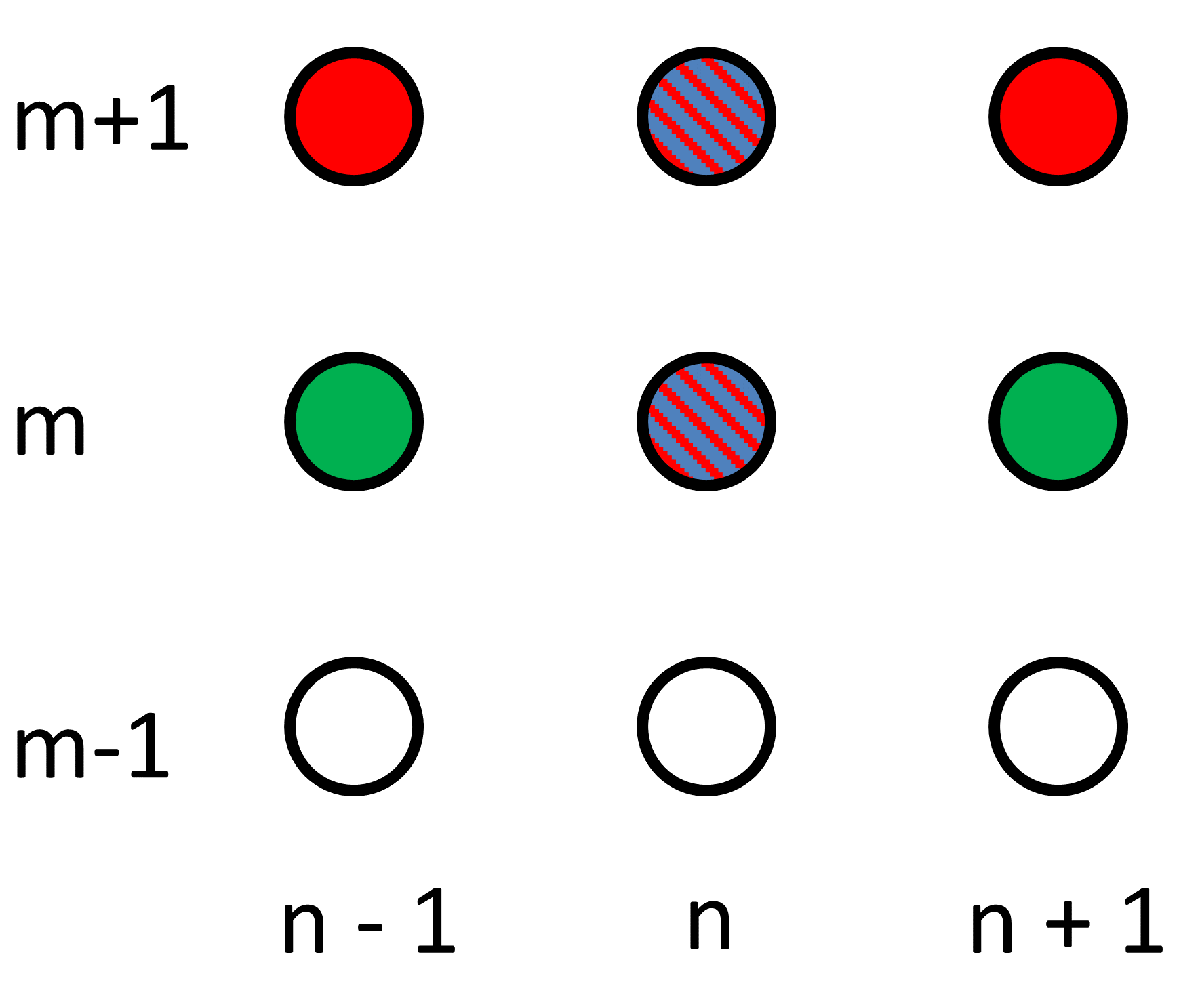            


$$(T^{m+1}_n - T^{m}_n) = F_n^m\ [T^{m+1}_{n+1}  - 2T^{m+1}_{n} +T^{m+1}_{n-1}] + F_{n}^m \phi_{n}^m (T^{m}_{n-1} - T^{m}_{n+1})^2$$



$$-F_n^mT^{m+1}_{n+1} +(1 +  F_n^m)  T^{m+1}_n -F_n^mT^{m}_{n-1} =T_n^m + F_{n}^m \phi_{n}^m (T^{m}_{n-1} - T^{m}_{n+1})^2$$



$$
{B}^m = [
\matrix{
1 + 2F_{1}^m & -F_{1}^m & 0 & \cdots & 0 \cr
-F_2^m & 1 + 2F_2^m & -F_2^m & \cdots & 0 \cr
0 & -F_3^m & 1 + 2F_3^m & \cdots & 0 \cr
\vdots & \vdots & \vdots & \ddots & -F_{N-1}^m \cr
0 & 0 & 0 & -F_N^m & 1 + 2F_N^m
}
]$$


Вектор $\vec{b}^m$ - нелинейная функция (квадратичная) такая же, как и в схеме 1

Таким образом неявная схема решения свелась к системе линейных уравнений для нахождения распределения температуры по толщине в следующий момент времени через предыдущие:


$$B^m\vec{T}^{m+1} =\vec{T}^m + \vec{b}^m$$


### Граничные условия Дирихле для чисто неявной схемы (схема 2)

Для применения граничных условий $T_1^m = f(t_m) = f^m$, $T_N^m = g(t_m) = g^m$ есть два варианта, как и для явной схемы.

- Можно модифицировать первую строку матрицы ${B}^m$  и вектор $\vec{b}^m$ так, чтобы система давала правильное решение:$
{B}^m = [
\matrix{
1  & 0 & 0 & \cdots & 0 \cr
-F_2^m & 1 + 2F_2^m & -F_2^m & \cdots & 0 \cr
0 & -F_3^m & 1 + 2F_3^m & \cdots & 0 \cr
\vdots & \vdots & \vdots & \ddots & -F_{N-1}^m \cr
0 & 0 & 0 & 0 & 1
}
]$, $\vec{b}^m_1 = f^{m+1} - f^m$, тогда первое уравнение системы будет давать тривиальное решение.И аналогично для последней строки.

- Можно решать усеченную систему уравнений: $
{B^*}^m = {B}^m(2:N-1,:) = [
\matrix{
-F_2^m & 1 + 2F_2^m & -F_2^m & &  \cr
&  & \ddots &  &  \cr
 & & -F_{N-1}^m & 1 + 2F__{N-1}^m & -F__{N-1}^m \cr
}
]$, тогда вместо системы из N уравнений можно решать систему из N-2 уравнений:

        
$${B^*}^m\vec{T}^{m+1}[2:N-1] =\vec{T}^m + \vec{b}^m$$


### Граничные условия Неймана для чисто неявной схемы (схема 2)

Чтобы задать граничные условия Неймана для неявной схемы применим те же рассуждения, что и ранее для явной схемы с "мнимым" узлом, для первого узла по координате, неявная схема дает:


$$-F_1^mT^{m+1}_{0} +(1 +  F_1^m)  T^{m+1}_1 -F_1^mT^{m+1}_2 =T_1^m + F_1^m \phi_n^m (T^m_{0} - T^{m}_{2})^2$$


Выражение для температуры получим из формулы центрального дифференцирования, аналогично явной схеме, однако ключевым отличием тут будет, что значение теплового потока, равно как и все температуры берутся из следующего момента времени (за исключением теплопроводности, которая берется с текущего момента времени): 


$$T_0^{m+1} = T_2^{m+1} - 2\Delta x \frac{q^{m+1}}{\lambda_1^m}$$


Обратим внимание на то, что нелинейный член включает в себя температуру мнимого узла в текущий $m$ - й момент времени:


$$T_0^m = T_2^m - 2\Delta x \frac{q^{m}}{\lambda_1^m}$$
 

Тут мы взяли $\lambda_1^m$ так как она нам известна, не знаю насколько это честно...

Подставив данное выражение в схему:


$$-F_1^m(T_2^{m+1} - 2\Delta x \frac{q^{m+1}}{\lambda_1^m}) +(1 +  2F_1^m)  T^{m+1}_1   -F_1^mT^{m+1}_{2} =T_1^m + 4 F_1^m \phi_n^m (\Delta x \frac{q^{m}}{\lambda_1^m})^2$$


Переносим неизвестные в левую часть:


$$(1 +  2F_1^m)  T^{m+1}_1    -2F_1^mT^{m+1}_{2} =   T_1^m + 4 F_1^m \phi_n^m (\Delta x \frac{q^{m}}{\lambda_1^m})^2  -2F_1^m \Delta x \frac{q^{m+1}}{\lambda_1^m}$$


Если принять, что матрица левой части $B^m$  имеет вид, то из выражения выше видно, что для чисто неявной схемы в ней ничего менять не нужно кроме второго элемента первой строки  - его надо увеличить в два раза, остальные изменения касаются правой части:

### Пример кода для чисто неявной схемы

## Схема 3. BFD1 = CN + explicit

Отличается от предыдущий использованием схемы Кранка-Николсона для аппроксимации второй производной, что дает второй порядок точности по времени

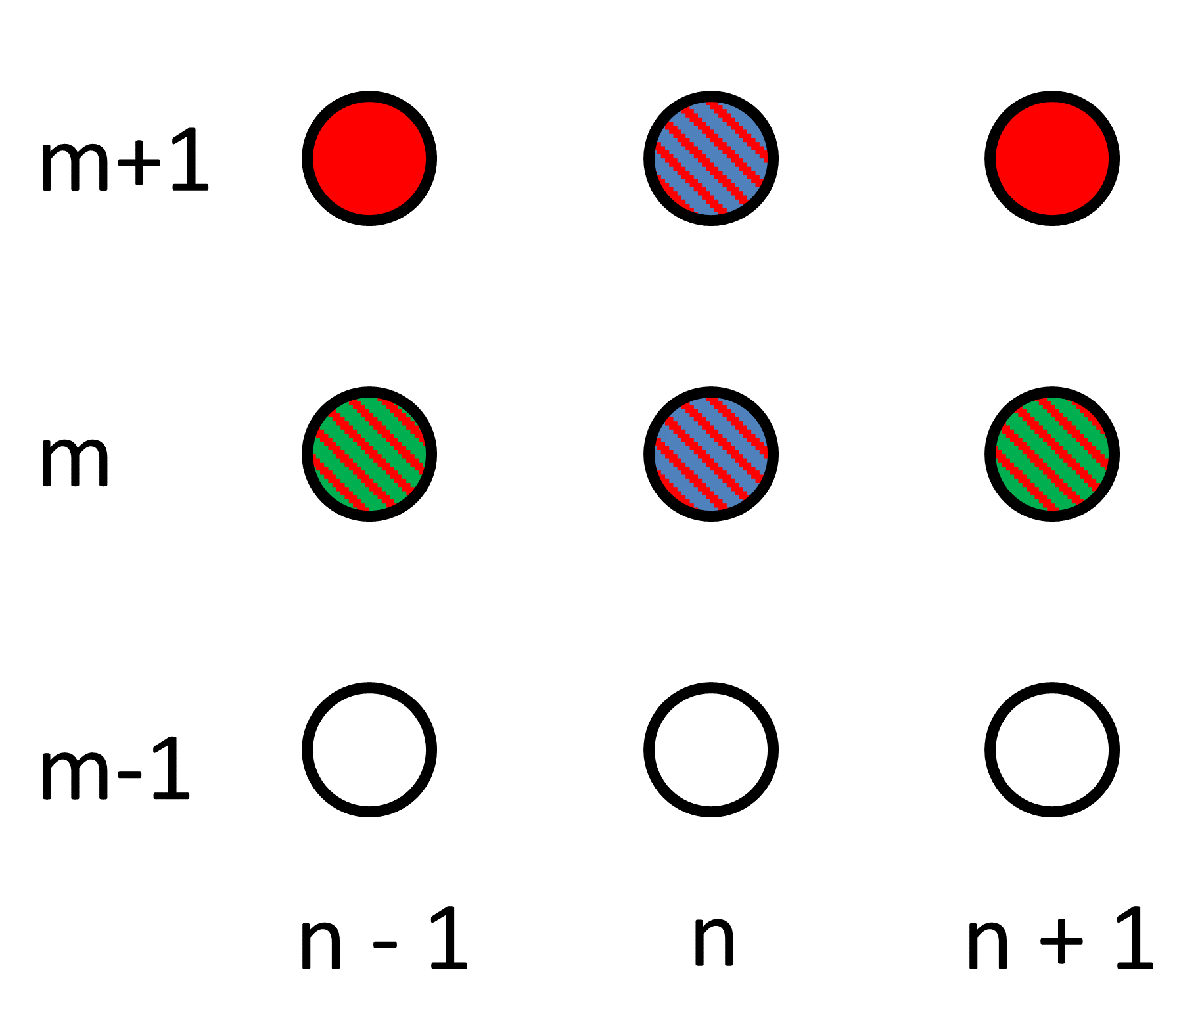                 


$$(T^{m+1}_n - T^{m}_n) =\frac{1}{2} (F_n^m[T^{m+1}_{n+1}  - 2T^{m+1}_{n} +T^{m+1}_{n-1}]) + \frac{1}{2} (F_n^m[T^{m}_{n+1}  - 2T^{m}_{n} +T^{m}_{n-1}])   + F_{n}^m \phi_{n}^m (T^{m}_{n-1} - T^{m}_{n+1})^2$$



$$-\frac{1}{2}F_n^mT^{m+1}_{n+1} + T^{m+1}_n (1 + F_n^m ) -\frac{1}{2} F_n^mT^{m+1}_{n-1} =\frac{1}{2}F_n^m T^{m}_{n+1} +  T^{m}_n(1 -  F_n^m) + \frac{1}{2}F_n^mT^{m}_{n-1}   +F_{n}^m \phi_{n}^m (T^{m}_{n-1} - T^{m}_{n+1})^2$$


В матричной форме это имеет вид:


$$C^m\vec{T}^{m+1} = N^m\vec{T}^m + \vec{b}^m$$


$
{C}^m = [
\matrix{
1 + F_{1}^m & - \frac{1}{2}F_{1}^m & 0 & \cdots & 0 \cr
-\frac{1}{2}F_{2}^m & 1 + F_{2}^m & -\frac{1}{2}F_{2}^m & \cdots & 0 \cr
0 & -\frac{1}{2}F_{3}^m & 1 + F_{3}^m & \cdots & 0 \cr
\vdots & \vdots & \vdots & \ddots & -\frac{1}{2}F_{N-1}^m \cr
0 & 0 & 0 & -\frac{1}{2}F_{N}^m & 1 + F_{N}^m
}
]$,

Вторая матрица также трехдиагональная


$$
N^m = [
\matrix{
1 - F_{1}^m & \frac{1}{2}F_{1}^m & 0 & \cdots & 0 \cr
\frac{1}{2}F_{2}^m & 1 - F_{2}^m & \frac{1}{2}F_{2}^m & \cdots & 0 \cr
0 & \frac{1}{2}F_{3}^m & 1 - F_{3}^m & \cdots & 0 \cr
\vdots & \vdots & \vdots & \ddots & \frac{1}{2}F_{N-1}^m \cr
0 & 0 & 0 & \frac{1}{2}F_{N}^m & 1 - F_{N}^m
}
]$$
 

Вектор $\vec{b}^m$ - нелинейная функция (квадратичная) такая же, как и в схеме 1

### Пример кода для схемы Кранка-Николсона (схема 3)

## Схема 4.BFD2 = implicit + explicit

Данная схема имеет ту же точность, что и предыдущая, но при этом использует полную неявную схему для второй производной и обратную производную второго порядка (**BFD2**).

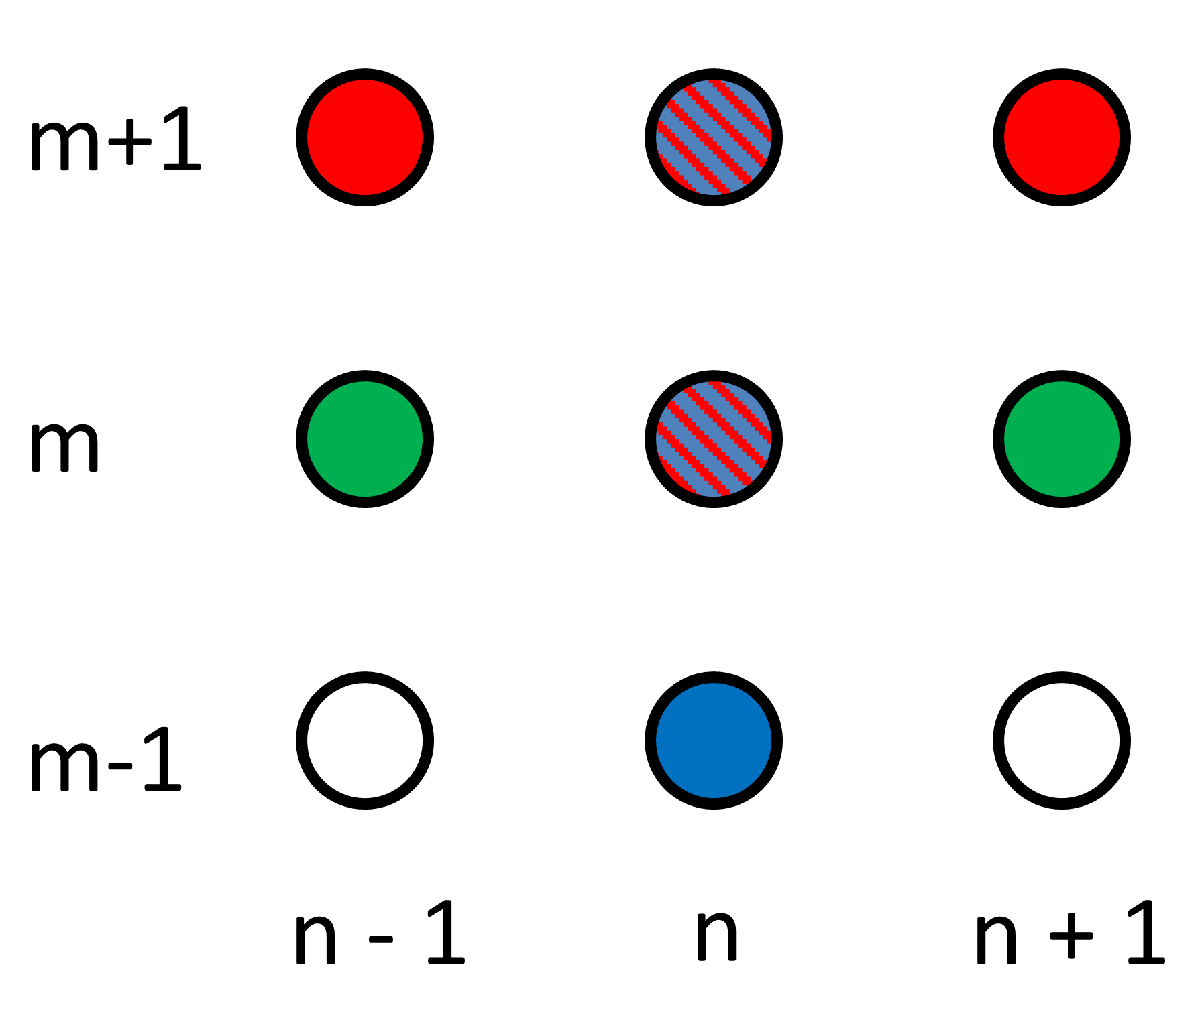            


$$\frac{3}{2}T^{m+1}_n - 2T^{m}_n + \frac{1}{2}T^{m-1}_n  =F_{n}^m[T^{m+1}_{n+1}  - 2T^{m+1}_{n} +T^{m+1}_{n-1}] + F_{n}^m \phi_{n}^m (T^{m}_{n-1} - T^{m}_{n+1})^2$$



$$ - F_{n}^mT^{m+1}_{n+1} +[\frac{3}{2} + 2 F_{n}^m] T^{m+1}_n  - F_{n}^mT^{m+1}_{n-1}  = 2T^{m}_n -\frac{1}{2}T^{m-1}_n  + F_{n}^m \phi_{n}^m (T^{m}_{n-1} - T^{m}_{n+1})^2$$



$$P^m\vec{T}^{m+1} = 2\vec{T}^m - \frac{1}{2}\vec{T}^{m-1} + \vec{b}^m$$



$$
{P}^m = [
\matrix{
\frac{3}{2} + 2F_{1}^m& - F_{1}^m  & 0 & \cdots & 0 \cr
-F_{2}^m & \frac{3}{2} + 2F_{2}^m & -F_{2}^m & \cdots & 0 \cr
0 & -F_{3}^m & \frac{3}{2} + 2F_{3}^m & \cdots & 0 \cr
\vdots & \vdots & \vdots & \ddots & -F_{N-1}^m \cr
0 & 0 & 0 & -F_{N}^m & \frac{3}{2}+ 2F_{N}^m
}
]$$


Вектор $\vec{b}^m$ - нелинейная функция (квадратичная) такая же, как и в схеме 1. Ключевым отличием данной схемы от схемы 2 является то, что для аппроксимации производной по времени используется схема второго порядка.

## Схема 5. BFD2 = СN + explicit

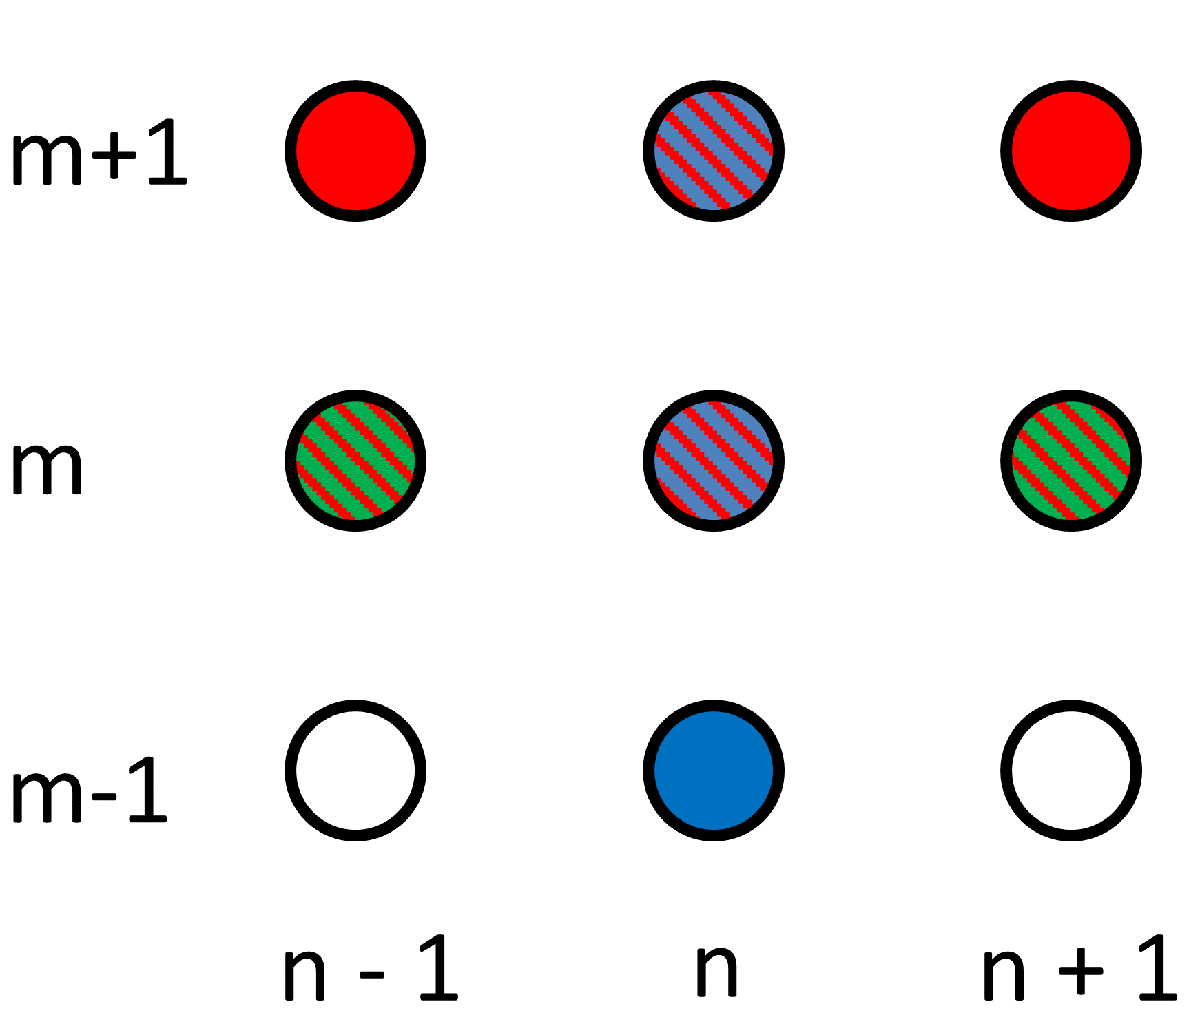                

Данная схема имеет ту же точность, что и предыдущая, но при этом использует схему Кранка-НИколсона для второй производной и обратную производную второго порядка (**BFD2**).

Левая часть тут получится такойже, как и у предыдущей схемы, а правая часть - похожа на схему 3, но с некоторыми модификациями


$$\frac{3}{2}T^{m+1}_n - 2T^{m}_n + \frac{1}{2}T^{m-1}_n  =\frac{1}{2} (F_{nm}[T^{m+1}_{n+1}  - 2T^{m+1}_{n} +T^{m+1}_{n-1}]) + \frac{1}{2} (F_{nm}[T^{m}_{n+1}  - 2T^{m}_{n} +T^{m}_{n-1}]) + F_{n}^m \phi_{n}^m (T^{m}_{n-1} - T^{m}_{n+1})^2$$



$$-\frac{1}{2} F_{nm}T^{m+1}_{n+1} +[\frac{3}{2} + F_{nm}] T^{m+1}_n  - \frac{1}{2}F_{nm}T^{m+1}_{n-1} = \frac{1}{2}F_{nm}T^{m}_{n+1} +  T^{m}_n(2 - F_{nm}) + \frac{1}{2}F_{nm}T^{m}_{n-1}   -\frac{1}{2}T^{m-1}_n  + F_{n}^m \phi_{n}^m (T^{m}_{n-1} - T^{m}_{n+1})^2$$



$$P^m\vec{T}^{m+1} = Q^m\vec{T}^m - \frac{1}{2}\vec{T}^{m-1} + \vec{b}^m$$



$$Q^m = [
\matrix{
2 - F_{m1} & \frac{1}{2}F_{m1} & 0 & \cdots & 0 \cr
\frac{1}{2}F_{m2} & 2 - F_{m2} & \frac{1}{2}F_{m2} & \cdots & 0 \cr
0 & \frac{1}{2}F_{m3}` & 2 - F_{m3} & \cdots & 0 \cr
\vdots & \vdots & \vdots & \ddots & \frac{1}{2}F_{m,N-1} \cr
0 & 0 & 0 & \frac{1}{2}F_{mN} & 2 - F_{mN}
}
]$$


Вектор $\vec{b}^m$ - нелинейная функция (квадратичная) такая же, как и в схеме 1, матрица $P^m$ такая же, как  в схеме 4

## Схема 6. BFD2 = СN + implicit

Схема практически полностью аналогична предыдущей, однако имеет существенной отличие, которое требует другого решателя системы уравнений!

для производной по времени - обратное дифференцирование второго порядка, для второй производной - схема К-Н, при этом для аппроксимации производной в нелинейной части теперь используется **неявная** схема!  

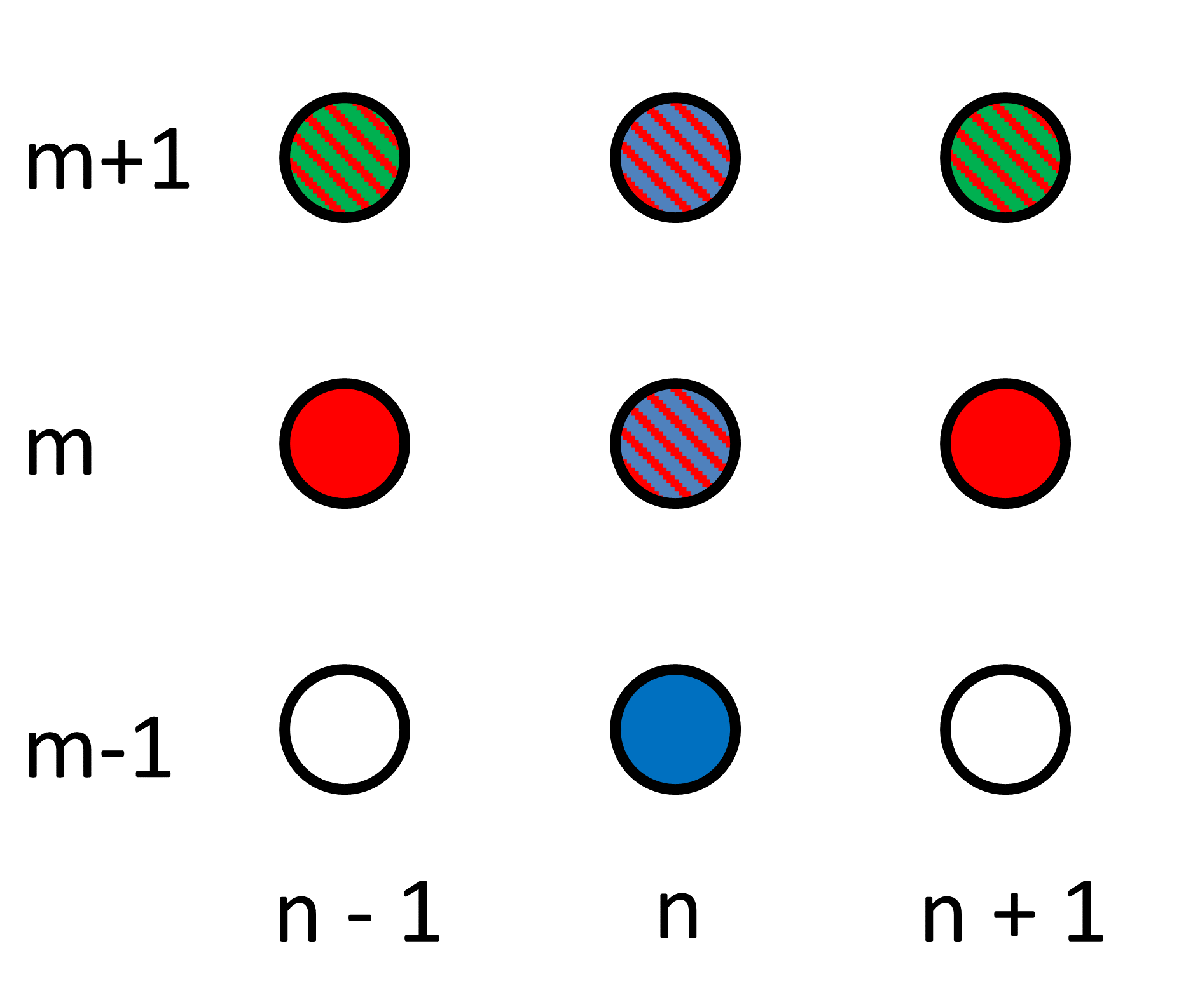                


$$P^m\vec{T}^{m+1} = Q^m\vec{T}^m - \frac{1}{2}\vec{T}^{m-1} + \vec{b'}^{m+1}(\vec{T}^{m+1} )$$


$\vec{b'}^{m+1}_n =F_{n}^m\phi_{n}^{m}(T_{n+1}^{m+1} - T_{n-1}^{m+1})^2$ - в нелинейной части, физические свойства берутся из $m$ - го момента времени, а вот производная по координате считается уже в неявном виде, поэтому вектор $\vec{b'}$ зависит от  $\vec{T}^{m+1}$ относительно просто.

Это уже система нелинейных уравнений, так как неизвестный вектор $\vec{T}^{m+1}$ сходит в правую часть в виде квадратичной функции. 

Для решения системы нелинейных уравнений может быть исопльзован метод Ньютона-Рафсона.

## Метод Ньютона-Рафсона

Если у нас есть система нелинейных уравнений:


$$\vec{\Phi}(\vec{x})=\vec{0}$$
 

 где $\vec{\Phi}$ - нелинейная векторная функция векторного аргумента, которая осуществляет взамно-однозначный "мэппинг" вектора размером $N\times 1$ в другой вектор того же размера $\vec{\Phi}: \mathcal{R}^N \to \mathcal{R}^N$

В методе Н-Р данная система решается итерационно, итерация по методу Н-Р имеет вид:


$$\vec{x}_{k+1} = \vec{x}_k - [\nabla\vec{\Phi}(\vec{x}_k)]^{-1}\vec{\Phi}(\vec{x}_k)$$


$k$ - индекс шага

$\nabla \vec{\Phi}(\vec{x}_k) = J(\vec{x}_k)$ - матрица Якоби (градиент вектора).

Метод следует опять-таки из разложения векторной функции в ряд Тейлора:


$$\vec{\Phi}( \vec{x} + \vec{p}) = \vec{\Phi}(\vec{x}) +  \nabla\vec{\Phi}(\vec{x})(\vec{p} ) +\frac{1}{2!}\vec{p}^T \nabla^2 \vec{\Phi}(\vec{x})\vec{p} + ... $$


Разложим в ряд Тейлора в окрестности точки $\vec{x}_k$:


$$\vec{\Phi}( \vec{x}_k) = \vec{\Phi}(\vec{x}^*) +  \nabla\vec{\Phi}(\vec{x}^*)(\vec{x}_k - \vec{x}^* ) + O(||x^* - x_k||^2) =  \nabla \vec{\Phi}(\vec{x}^*)(\vec{x}_k - \vec{x}^* ) + O(||x^* -  x_k||^2)$$


Подставив в формулу для шага метода Н-Р получим:


$$\vec{x}_{k+1} - \vec{x}^* = \vec{x}_k - \vec{x}^*  - [\nabla\vec{\Phi}(\vec{x}_k)]^{-1} [\nabla \vec{\Phi}(\vec{x}^*)(\vec{x}_k - \vec{x}^* )  + O(||x^* -  x_k||^2)]$$
 

Из формулы выше видно, что когда $\nabla\vec{\Phi}(\vec{x}_k) =\nabla \vec{\Phi}(\vec{x}^*)$ алгоритм сходится к решению $\vec{x}_{k+1} =  \vec{x}^*$ с точностью второго порядка

Отличие от метод Ньютона в оптимизации:

 - В задачах оптимизации, мы решаем переопределенную систему, где число уравнений больше числа неизвестных, здесь они равны

 - Метод Ньютона в оптимизации - требует расчета матрицы вторых производных (матрица Гесса)

 - Если применить метод Ньютона-Рафсона к выражению для **градиента** невязки в задаче оптимизации, то есть искать решение, которое дает нулевой градиент, то мы получим метод Ньютона для оптимизации.

### Применение метода Ньютона-Рафсона для схемы 6 - аналитическое выражение для Якобиана

Для применения метода Ньютона-Рафсона к схеме BFD2 - СТ - implicit, выражение перепишем в виде системы нелинейных уравнений, чтобы решать их методом Ньютона-Рафсона:


$$\vec{\Phi}(\vec{X})=P^m\vec{X} -  \vec{b'}(\vec{X}) + \frac{1}{2}\vec{T}^{m-1} - Q^m\vec{T}^m = \vec{0}$$


Неизвестным тут является вектор $\vec{X} \equiv \vec{T}^{m+1}$

Чтобы итерационно решать систему $\vec{\Phi}(\vec{X})= \vec{0}$необходимо уметь вычислять матрицу якоби $\nabla_{\vec{X}}\vec{\Phi}$, 

в выражении для $\vec{\Phi}$ первые два слагаемых зависят от неизвестной (распределения температуры по толщине на следующем шаге),

а вторые два слагаемых - только от известных температур в предыдущие моменты времени.

В данном случае, матрица якоби задачи может быть достаточно просто посчитана аналитически. 

Для первого слагаемого все просто: 


$$\nabla_{\vec{X}}[P^m\vec{X}] = P^m$$


Для второго слагаемого ситуация сложнее:

Формулу для вектора $\vec{b'}$ можно переписать в матричном виде (первая и последняя строки этой матрицы - неправильные, так как зависят от типа граничных условий):


$$\[
D =[
\matrix{
0 & -1 & 0 & \cdots & 0 \cr
1 & 0 & -1 & \cdots & 0 \cr
\vdots & & \ddots & \ddots & \vdots \cr
0 & \cdots & 1 & 0 & -1 \cr
0 & \cdots & \cdots & 1 & 0
}
]$$


$\vec{b'}(\vec{X})= \mathrm{diag}(\vec{F}^{m}\circ\vec{\phi}^{m})(D\vec{X}\circ D\vec{X})$  , где $\vec{F}^m = \matrix{ F_1^m \cr \vdots \cr F_N^m}$ , $\vec{\phi}^m = \matrix{ \phi_1^m \cr \vdots \cr \phi_N^m}$ - вектора коэффициентов 

 $\circ$ - поэлементное умножение (произведение Адамара) $\vec{c}(\vec{x}) = \vec{a} \circ \vec{b}$ : $[\vec{c}]_i = [\vec{a}]_i[\vec{b}]_i$ : $\vec{c} =[ \matrix{a_1b_1 \cr \vdots \cr a_n b_n}]$

$\mathrm{diag}(\vec{a})$ - операция диагонализации вектора, $\mathrm{diag}(\vec{a}) = [ \matrix{a_1 & \dots &0\cr 0&\ddots & 0\cr 0 & \dots & a_N  }]$

Операция  $\mathrm{diag}(\vec{a})A$ умножает каждую строку матрицы на соответствующую координату вектора $\vec{a}$, если умножать матрицу справа $A\cdot \mathrm{diag}(\vec{a})$ на диагонализованный вектор, то каждый столбец матрицы умножается на соотвествующую координату

clearvars
a = sym('a',[3,1]);
b = sym('b',[2,1]);
C = sym('c',[3,2]);
diag(a)*C

$$ans = \left(\begin{array}{cc} a_{1}\,c_{1,1} & a_{1}\,c_{1,2}\\ a_{2}\,c_{2,1} & a_{2}\,c_{2,2}\\ a_{3}\,c_{3,1} & a_{3}\,c_{3,2} \end{array}\right)$$

C*diag(b)

$$ans = \left(\begin{array}{cc} b_{1}\,c_{1,1} & b_{2}\,c_{1,2}\\ b_{1}\,c_{2,1} & b_{2}\,c_{2,2}\\ b_{1}\,c_{3,1} & b_{2}\,c_{3,2} \end{array}\right)$$

% в матлаб произведение адамара работает добавлением точки 
a.*C

$$ans = \left(\begin{array}{cc} a_{1}\,c_{1,1} & a_{1}\,c_{1,2}\\ a_{2}\,c_{2,1} & a_{2}\,c_{2,2}\\ a_{3}\,c_{3,1} & a_{3}\,c_{3,2} \end{array}\right)$$

C.*transpose(b)

$$ans = \left(\begin{array}{cc} b_{1}\,c_{1,1} & b_{2}\,c_{1,2}\\ b_{1}\,c_{2,1} & b_{2}\,c_{2,2}\\ b_{1}\,c_{3,1} & b_{2}\,c_{3,2} \end{array}\right)$$

 Так как вектор $\vec{b'}(\vec{x})$ содержит произведение Адамара двух векторов, то вначале получим формулу для дифференцирования произведения Адама двух векторных функций, зависящих от векторного аргумента. 

$\vec{c}(\vec{x}) = \vec{a}(\vec{x}) \circ \vec{b}(\vec{x})$  $\vec{c} =[ \matrix{a_1 (\vec{x}) b_1(\vec{x}) \cr \vdots \cr a_n(\vec{x}) b_n (\vec{x})}]$, тогда 


$$\nabla_{\vec{x}}\vec{c} = [\matrix{
 \nabla [ a_1 (\vec{x}) b_1(\vec{x}) ]\cr
 \vdots \cr
 \nabla[a_n(\vec{x}) b_n (\vec{x})]}] =  [\matrix{
 \nabla [ a_1 (\vec{x})] b_1(\vec{x}) \cr
 \vdots \cr
 \nabla[a_n(\vec{x})] b_n (\vec{x})}]  + [\matrix{
 a_1 (\vec{x}) \nabla [ b_1(\vec{x}) ]\cr
 \vdots \cr
a_n(\vec{x})  \nabla[b_n (\vec{x})]}]  = \mathrm{diag}(\vec{b})\nabla\vec{a} + \mathrm{diag}(\vec{a})\nabla\vec{b}$$


То есть, градиент вектора (матрица Якоби) произведения Адамара двух векторных функций - это сумма  матриц Якоби этих вух функции, в которых каждая строка умножена на соотвествующую координату второй функции. 

В соответствии с этим выражением легко получить формулу для матрицы Якоби вектора $\vec{b'}(\vec{x})$:


$$\nabla_{\vec{X}} \vec{b'}(\vec{X})= \nabla [\mathrm{diag}(\vec{F}_{m}\circ\vec{\phi}_{m})(D\vec{X}\circ D\vec{X})] = 
\mathrm{diag}(\vec{F}_{m}\circ\vec{\phi}_{m}) \nabla [(D\vec{X}\circ D\vec{X})] = 
\mathrm{diag}(\vec{F}_{m}\circ\vec{\phi}_{m}) [\mathrm{diag}(D\vec{X})\nabla[D\vec{X}]   + D\vec{X})\nabla[D\vec{X}] ] = 
2\mathrm{diag}(\vec{F}_{m}\circ\vec{\phi}_{m} \circ (D\vec{X}))D$$
 

Итого, окончательное выражение для $k$-й итерации метода Ньютона-Рафсона для схемы **BFD2 - СТ - implicit **будет иметь вид:


$$\vec{\Phi}(\vec{X}_k)=P^m\vec{X}_k -  \vec{b'}(\vec{X}_k) + \frac{1}{2}\vec{T}^{m-1} - Q^m\vec{T}^m$$



$$\nabla \vec{\Phi}(\vec{X}_k)= P^m + 2\mathrm{diag}[\vec{F}^{m}\circ\vec{\phi}^{m} \circ (D\vec{X}_k)]D$$



$$\vec{X}_{k+1} = \vec{X}_k - (\nabla \vec{\Phi}(\vec{X}_k))^{-1}\vec{\Phi}(\vec{X}_k)$$


syms x1 x2 real
A = sym('a',[2,2]);
jacobian(A*[x1;x2],[x1;x2])

$$ans = \left(\begin{array}{cc} a_{1,1} & a_{1,2}\\ a_{2,1} & a_{2,2} \end{array}\right)$$

F = A*[x1;x2] .* A*[x1;x2];
J = jacobian(F, [x1 x2])

$$J = \begin{array}{l} \left(\begin{array}{cc} a_{1,1}\,\sigma_{2}+{a_{1,1}}^{2}\,x_{1}+a_{1,1}\,a_{1,2}\,x_{2} & a_{1,2}\,\sigma_{2}+{a_{1,2}}^{2}\,x_{2}+a_{1,1}\,a_{1,2}\,x_{1}\\ a_{2,1}\,\sigma_{1}+{a_{2,1}}^{2}\,x_{1}+a_{2,1}\,a_{2,2}\,x_{2} & a_{2,2}\,\sigma_{1}+{a_{2,2}}^{2}\,x_{2}+a_{2,1}\,a_{2,2}\,x_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=a_{2,1}\,x_{1}+a_{2,2}\,x_{2}\\ \sigma_{2}=a_{1,1}\,x_{1}+a_{1,2}\,x_{2} \end{array}$$

## Схема 7. BFD2 - СN - implicit  + implicit material properties

                

Эта схема отличается от предыдущей тем, что материальные свойства тоже берутся в неявной форме, то есть:


$$P^{m+1}\vec{T}^{m+1} = Q^{m+1}\vec{T}^m - \frac{1}{2}\vec{T}^{m-1} + \vec{b}^{m+1}(\vec{T}^{m+1} )$$


Теперь мы не только считаем производные для $m+1$ -го момента времени, но и теплофизические свойства рассчитываем из неявной схемы.

$b_n^{m+1} = F_{n}^{m+1}\phi_{n}^{m+1}(T^{m+1}_{n-1} - T^{m+1}_{n+1})^2$ , также и все матрицы теперь тоже зависят от распределения температуры для $m+1$ -го момента времени


$$\vec{b}(\vec{T}^{m+1})= \mathrm{diag}(\vec{F}^{m+1}\circ\vec{\phi}^{m+1})(D\vec{T}^{m+1}\circ D\vec{T}^{m+1})$$


Функция невязки для метода Ньютона-Рафсона будет иметь вид:

$\vec{\Phi}(\vec{X})=P(\vec{X})\cdot\vec{X} -  \vec{b}(\vec{X}) + \frac{1}{2}\vec{T}^{m-1} - Q(\vec{X})\vec{T}^m$ - матрицы $P$ и $Q$ теперь являются функциями неизвестной переменной $\vec{X} \equiv \vec{T}^{m+1}$

В этой системе нелинейных уравнений все члены кроме $\frac{1}{2}\vec{T}^{m-1}$ и  $\vec{T}^m$ зависят от неизвестного вектора $\vec{X}$

## Тесты различных функций

Ниже приводятся результаты тестирования различных функций для конечно-разностного решения уравнения теплопроводности

clearvars
% BOUNDARY CONDITIONS SETTINGS

UPPER_BC_TYPE = 3;
LOWER_BC_TYPE = 3;

% граничные условия третьего рода
heat_transfer_up = 90;% коэффициент теплоотдачи сверху
Text_up = 0;% температура восстановления 
% граничные условия третьего рода 
heat_transfer_dwn = 90;% коэффициент теплоотдачи снизу
Text_dwn = 0;% температура восстановления

tmax = 100;% режим нагрева


lam_pars =[3e-7,...
    0,...
    15.732];


heating_rate = 20

heating_rate = 20

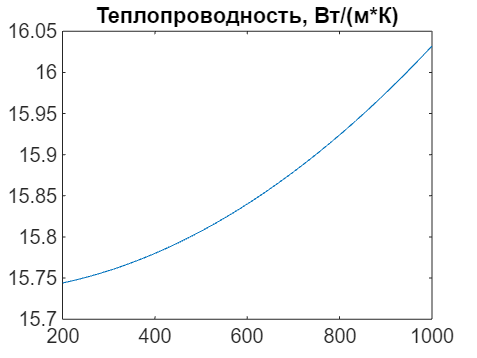

Tmax = 1000; % максимальная температураs



lam_fun = @(T)polyval(lam_pars,T); % теплопроводность
lam_der_pars = polyder(lam_pars); % коэффициенты производной
lam_der = @(T)polyval(lam_der_pars,T);% производная теплопроводности
plot(linspace(200,1000,30),lam_fun(linspace(200,1000,30)));title("Теплопроводность, Вт/(м*К)")

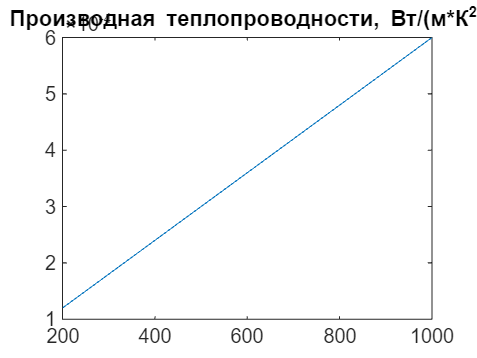

plot(linspace(200,1000,30),lam_der(linspace(200,1000,30)));title("Производная теплопроводности, Вт/(м*К^2)")




N = 50;% число точек сетки по координате
M = 15000;% число точек сетки по времени

Tinit = 20; % начальная температура
Cp = 1000; % теплоемкость
Ro = 2700;% плотность
H = 15e-3; % толщина слоя в мм
Cp_fun = @(T) Cp*Ro*ones(size(T));% не зависит от температуры
initT_f = @(X) Tinit*ones(size(X));% стартовая температура постоянна
switch UPPER_BC_TYPE 
    case 1
        BC_up_f = @(t)heat_and_sustain(t, Tinit,Tmax,heating_rate)   
    case 2
        BC_up_f = @(t) 1e6*ones(size(t));
    case 3
        BC_up_f = @(T) heat_transfer_up*(T - Text_up)
end

BC_up_f = function_handle with value:
    @(T)heat_transfer_up*(T-Text_up)



switch LOWER_BC_TYPE
    case 1
        BC_dwn_f = @(t) Tinit*ones(size(t));% температура снизу постоянна
    case 2
        BC_dwn_f = @(t) Tinit*zeros(size(t));
    case 3
        BC_dwn_f = @(T) heat_transfer_dwn*(T - Text_dwn)        
end

BC_dwn_f = function_handle with value:
    @(T)heat_transfer_dwn*(T-Text_dwn)


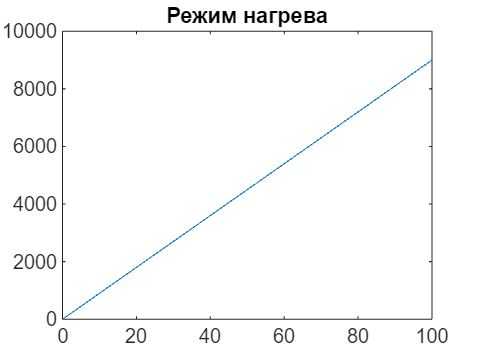


plot(linspace(0,tmax,100),BC_up_f(linspace(0,tmax,100)));title("Режим нагрева")

% решаем диффур
tic
[T,x,t,maxFn] = explicit_case1(Cp_fun, lam_fun,lam_der, H, ...
    tmax,initT_f,BC_up_f,BC_dwn_f,M,N,UPPER_BC_TYPE,LOWER_BC_TYPE);

explicit_case1 is not found in the current folder or on the MATLAB path, but exists in:
    E:\projects\matlab-seminar\applications\InverseHeatTransfer\sem27\sem27_deps

Change the MATLAB current folder or add its folder to the MATLAB path.

toc
[xp,tp] = meshgrid(x,t(1:100:end));
surf(tp,1e3*xp,T(:,(1:100:end))');title("Fmax = "+ maxFn)
xlabel("Время,с")
ylabel("Координата, мм")
zlabel("Температура, ^оС")
plot(T(:,1:(M/50):end))
%{
tic
T2 = explicit_case1_dirichle2(Cp_fun, lam_fun,lam_der, H, ...
    tmax,initT_f,BC_up_f,BC_dwn_f,M,N);
toc
surf(T2(:,1:100:end))
surf(T2(:,1:100:end) - T(:,1:100:end));title("Разница матричного варианты и через циклы")

tic
[T_imp,x,t,maxFn] = implicit_case2_dirichle(Cp_fun, lam_fun,lam_der, H, ...
    tmax,initT_f,BC_up_f,BC_dwn_f,M,N);
toc
norm(T_imp-T2)
surf((T_imp(:,1:100:end) - T(:,1:100:end))./T(:,1:100:end));

tic
TCN= CN_case3_dirichle(Cp_fun, lam_fun,lam_der, H, ...
    tmax,initT_f,BC_up_f,BC_dwn_f,M,N);
toc
norm(T_imp-TCN)
surf(T_imp(:,1:100:end)-TCN(:,1:100:end))
%}

### Граничные условия и возможность восстановления температуры

С начальным условием все более-менее понятно, оно дает нам соотвественно первую строку матрицы $T_{n}^1$ 


$$T_n^1 = \phi(x_n)$$


В матрицах конечно-разностных схем явно что-то не так с первой и последней строками. 

Предположим, что теплофизика не зависит от температуры, а это значит, что вектор  $\vec{b}^m$ не будет иметь нелинейного члена и станет равным просто вектору$\vec{T}^m$, также для простоты, пусть сетка выбрана такой, что $F_{mn}=\frac{a_{mn}\Delta t}{\Delta x^2} = 1$ и у нас равномерное распределения температуры по толщине, такое решение должно давать тривильную форму

N = 100;
A = toeplitz([3,-1,zeros(1,N-2)])

A =      3    -1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
    -1     3    -1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0    -1     3    -1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0    -1     3    -1     0     0     0     0     0     0     0     0     0     0   

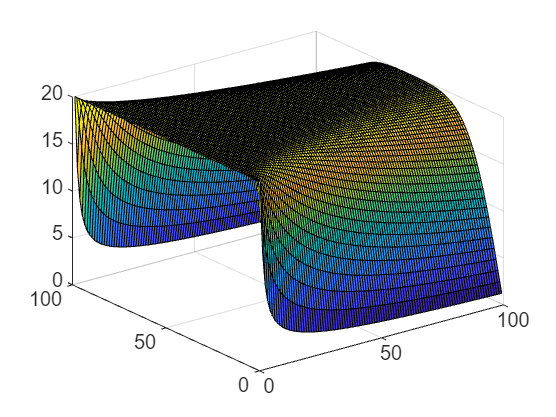

T0 = 20*ones(N,1);
T = zeros(N);
T(:,1) = T0;
for ii=2:N
    T(:,ii) = A\T(:,ii-1);
end
surf(T)

Нам нужно, чтобы матрица при решении задачи всегда давала заданное значение первой координаты вектора  $\vec{T}^{m}$: $T_1^m(t_m) = f(t_m)= f^m$  

Как вариант  можно модифицировать матрицу $B_m$, 


$$
{B}_m  \vec{T}^{m+1}  = \vec{b}^m$$


насчет первой строки понятно, ее можно сделать тривиальной:


$$[
\matrix{
1 & 0 & 0 & \cdots & 0 \cr
-F_{m2} & 1 + 2F_{m2} & -F_{m2} & \cdots & 0 \cr
0 & -F_{m3} & 1 + 2F_{m3} & \cdots & 0 \cr
&&&\ddots&&\cr
\vdots & \vdots & F_{m,N-1} & 1 + 2F_{m,N-1} & -F_{m,N-1} \cr
0 & 0 & 0 & -F_{mN} & 1 + 2F_{mN}
}
] [ \matrix{T_1^{m+1} \cr \vdots  \cr T_N^{m+1}}]= [\matrix{b_1^m \cr \vdots \cr b_N^m}]$$


При этом мы должны поменять первую и вторую координаты вектора $\vec{b}^m$

$b_1^m =T_1^{m+1}  =  f(t_{m+1}) = f^{m+1}$,


$$b_2^m = T_2^m + F_{m2}\phi_{m2} (T_1^m - T_3^m)^2 + F_{m2}T_1^{m+1}$$


Остальные остаются без изменений, таким образом, добавление граничных условий влияет на 

непосредственно элемент сетки, куда добавляем, а также на соседний.

Однако данный способ не идеален, так как исходная матрица была трехдиагональной, а теперь стала полной, для трехдиагональных матриц существует специальный быстрый солвер (при решении системы при помощи mldivide)

Для учета граничных условий и расчета теплового потока, рекомендуется использовать разностные соотношения второго порядка точности, учитывающие накопление тепла на предыдущем шаге:

$q^{m+1}=\frac{\lambda_1^m}{\Delta x}(T_1^{m+1} - T_2^{m+1}) + C_1^m\frac{\Delta x}{2\Delta t}(T_1^{m+1} - T_1^m) $ - тепловой поток сверху

$\tilde q^{m+1}=\frac{\lambda_N^m}{\Delta x}(T_N^{m+1} - T_{N-1}^{m+1}) + C_0^m\frac{\Delta x}{2\Delta t}(T_N^{m+1} - T_N^m) $ - тепловой поток снизу

В матричной форме данные уравнения будут иметь вид0

Рассмотрим одномерную задачу теплопроводности


$$\begin{cases} \matrix{
 C(T) \frac{\partial T}{\partial t}  = \frac{\partial }{\partial x}( \lambda(T) \frac{\partial T}{\partial x}) \cr 
T(x,0) = \phi(x),x   \in [0,b] \cr
T(d,t) = f(t), t \in [0,t_m] \cr
-\lambda(T(b,t))\frac{\partial T}{\partial x} (b,t) = \tilde q(t)


} \end{cases}$$


Это уравнение в частных произодных, с двумя переменными - время и координата, толщина образца $b$, $d$ - точка расположения термопары.Кроме того, мы знаем распределение температуры по толщине образца в начальный момент времени $\phi(x)$, зависимость температуры от времени на некоторой глубине $d$, которая задачется функцией $f(t)$ и зависимость от времени теплового потока через нижнюю границу $\tilde{q}(t)$.

$C(T)$ -  теплоемкость образца, она выражается через его удельную теплоемкость и плотность:$С(T) = c_v(T)\rho$. 

$\lambda(T)$ - коэффициент теплопроводности 

 Если $d=0$ - уравнение становится прямой задачей, с граничными условиями первого рода (температура) сверху и второго рода (тепловой поток) снизу. Собственно, в области $x \in [d,b]$ задача является прямой и решается однозначно. А вот в область $x \in [0,d]$ решение требуется продлить, восстановив граничные условия и температуру на верхней границе (то есть, это задача восстановления граничных условий). Задача в такой формулировке удобна, так как на практике, даже если мы ставим целью измерить температуры на поверхности слоя, термопары все равно должны заделываться на некоторую глубину под поверхностью образца, измерить температуру нагреваемой поверхности при помощи термопары невозможно.

Пусть нам известна зависимость температуры от времени сверху  и тепловой поток снизу слоя.

Предполжим, что температура у нас имеет следующую форму, это матрица $[T]$, элемент $T_l^n$ которой, стоящий на $m$ -й строке $n$ - го столбца представляет собой температуру в $m$ - й момент времени для точки с $n$ - й координатой. Данная матрциа имеет размерность $M \times N$.


$$\begin{cases} \matrix{
\frac {1}{a(T)} \frac{\partial T}{\partial t}  =\frac{\partial^2 T}{\partial x^2} +   \frac{\lambda'(T)}{\lambda(T)} (\frac{\partial T}{\partial x})^2 \cr 
T(x,0) = \phi(x),x   \in [0,b] \cr
T(0,t) = f(t), t \in [0,t_m] \cr
-\lambda(T(b,t))\frac{\partial T}{\partial x} (b,t) = \tilde {q}(t)
} \end{cases}$$


FUNTIONS

% функция для решения уравнения теплопроводности при помощи явной схемы
% первого порядка и явной схемы 

function D = Dt(M)
% M- number of input matrix rows
    persistent Di 
    if isempty(Di) || M~=size(Di,1)
        Di = zeros(M-1,M);
        Di(diagonal_inds(0,M-1,M)) = -1;
        Di(diagonal_inds(1,M-1,M)) = 1;
    end
    D = Di;
end

function D = Dtsym(M)
% M- number of input matrix rows
    D = zeros(M-1,M);
    D(diagonal_inds(-1,M-1,M)) = -1/2;
    D(diagonal_inds(1,M-1,M)) = 1/2;
end
function D = D2t(N)
    D = zeros(N,N);
    D(diagonal_inds(0,M-1,M)) = -2;
    D(diagonal_inds(1,M-1,M)) = 1; 
    D(diagonal_inds(-1,M-1,M)) = 1;
end
function T = heat_and_sustain(t, Tinit,Tmax,q)
    dT = Tmax - Tinit;
    T = zeros(size(t));
    f =  t >= dT/q;
    T(f) = Tmax;
    T(~f) = q*t(~f);
end